Hola, Bienvenido a la red Adaline\n


Selecciono la red en modo CLASIFICADOR


El numero de rasgos es: 2


El numero de clases ingresadas es: 4


El numero de neuronas necesarias es: 2


Epoca número: 1


Epoca número: 2


Epoca número: 3


Epoca número: 4


Epoca número: 5


Epoca número: 6


Epoca número: 7


Epoca número: 8


Epoca número: 9


Epoca número: 10


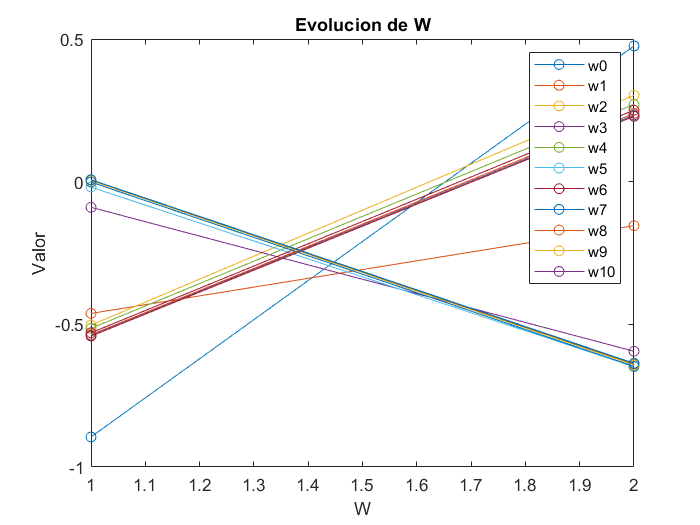

Epoch


    0.0818



W


   -0.5412    0.0070
    0.2290   -0.6364



Bias


    0.0258
    0.2316



La red no convergió vuelva a intentarlo


Hola, Bienvenido a la red Adaline\n


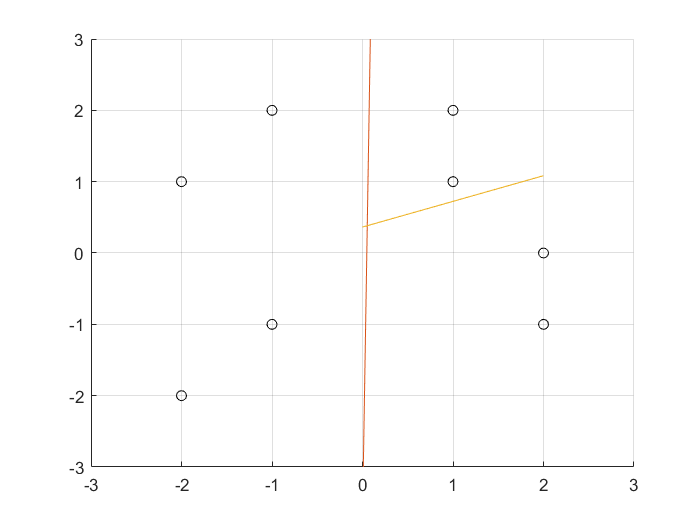

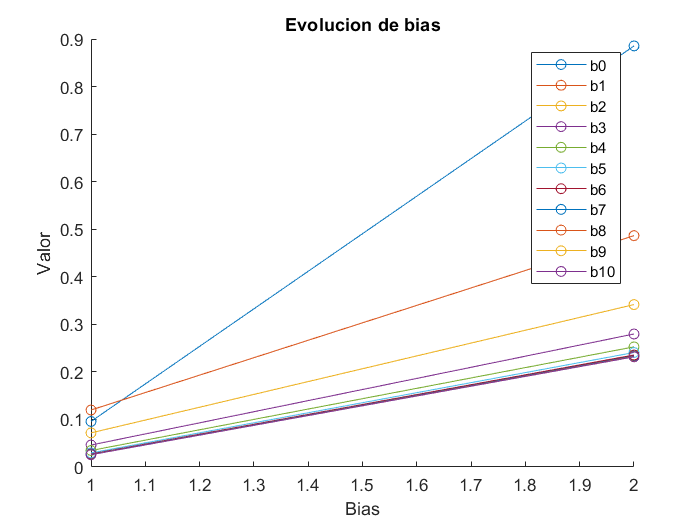

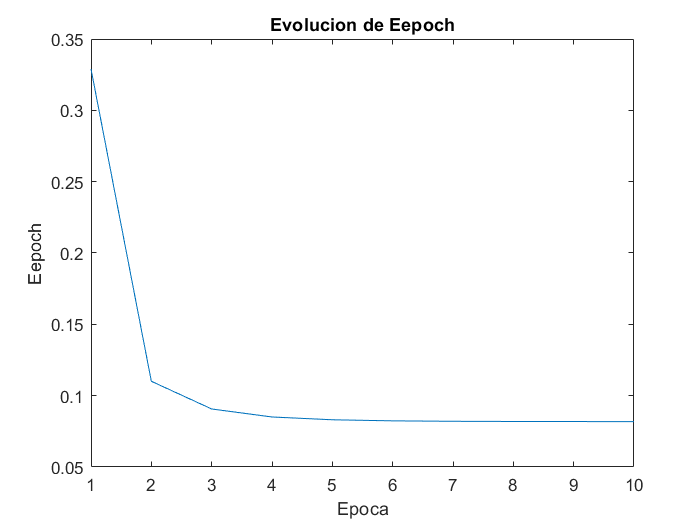

clearvars
epochMax = 5;
Eepoch = 0.00;
alpha = 0.04;
flag = 1;

while flag == 1
    disp("Hola, Bienvenido a la red Adaline\n");
    opt = input('Seleccione 0 Modo REGRESOR 1 modo CLASIFICADOR otro SALIR\n');
    disp('Valor de Alpha:');
    disp(alpha);
    disp('Valor de Eepoch');
    disp(Eepoch);
    if opt == 0
        disp('Selecciono la red en modo REGRESOR');
        epochMax = input('Introduzca el numero de epochMax\n')
        data = load('codificador12bits.txt');
        X = data(:,1:end-1);
        y = data(:,end);
        [m,R] = size(X);
        %Iniamos los pesos entre -1 y 1
        W = -1 + 2.*rand(R,1);
        figure('Name','Evolucion de W');
        plot (W, '-o');
        title ('Evolucion de W');
        xlabel ('W');
        ylabel ('Valor');
        disp("Generando matriz de pesos...");
        e = zeros(m,1);
        a = zeros(m,1);
        Eepoch_v = [];
        array= 'w0';
        hold on
        for j = 1:epochMax
            
            disp("Epoca número: "+j);
            %Iniciamos las épocas de aprendizaje
            for i=1:m
                a(i) = X(i,:)*W;
                e(i) = y(i)-a(i);
                if(e(i) == 0)
                    continue;
                else
                    W = W + (2.*alpha.*e(i).*(X(i,:)'));
                end
            end
            %Ploteamos W
            label = sprintf ("w%d", j);
            aux = [array label];
            array = aux;
            plot (W, '-o');
            
            error = abs(sum(e.^2))/m;
            aux = [Eepoch_v error];
            Eepoch_v =  aux;
            if error <= Eepoch
                flag = 0;
                disp("La red convergió")
                break
            end
        end
        label = sprintf ("w%d", j);
        aux = [array label];
        array = aux;
        plot (W, '-o');
        hold off
        legend (array);
        disp('Valores finales');
        disp('Epoch');
        disp(Eepoch_v(:,end));
        disp('W');
        disp(W);
        file = fopen ('valores_finales_RNA_regresion_12_bits.txt','w');
        fprintf(file, 'W\n');
        fprintf (file,'%f ',W);
        fclose(file);
        
        figure('Name','Evolucion de Eepoch');
        plot(Eepoch_v);
        title ('Evolucion de Eepoch')
        xlabel ('Epoca');
        ylabel ('Eepoch');
    
        
    elseif opt == 1
        disp('Selecciono la red en modo CLASIFICADOR');
        %Leer Datoss
        load input_p.txt
        load input_XOR.txt
        load input_p_2.txt
        load target.txt
        load target_XOR.txt
        load target_2.txt
        X = input_p_2;
        y = target_2;
        [m,R] = size(X);%R = rasgos
        S = size(y,2);%S = neuronas
        num_cls = m/2;
        disp("El numero de rasgos es: "+R);
        disp("El numero de clases ingresadas es: "+ num_cls);
        disp("El numero de neuronas necesarias es: "+ S);
        %Epocas de aprendisaje
        % Matriz de pesos  y bias%
        W = -1 + 2.*rand(S,R);
        b = -1 + 2.*rand(S,1);
        %Aqui empieza el aprendizaje
        %Solicitamos el numero de iteraciones
        CU=0;
        epochMax=input('Ingrese el numero de MAX_EPOCH:');
        e = zeros(m,S);
        a = zeros(m,S);
        error =zeros(m,1);
        %Calcular la salida de la red
        bias = b;
        Eepoch_v = [];
        figure('Name','Evolucion de W');
        plot (W, '-o')
        title ('Evolucion de W')
        xlabel ('W')
        ylabel ('Valor')
        array= 'w0';
        hold on;
        for j =1 :epochMax
            disp("Epoca número: "+j);
            for i = 1:m
                a(i,:) = (purelin(W*X(i,:)' + b))';
                %Calcular el error
                e(i,:) = y(i,:) - a(i,:);
                %Nuevos valores de los pesos y bias
                if e(i,:) == zeros(1,S)
                    error(i) = sum( e(i,:) );
                    continue;
                else
                    W = W + ( 2.*alpha.*e(i,:)'*X(i,:) );
                    b = b + ( 2.*alpha.*e(i,:)' );
                    error(i) = sum( (e(i,:).^2)/(2*m*S) );
                end
            end
            
            label = sprintf ("w%d", j);
            aux = [array label];
            array = aux;
            plot(W,'-o');

            suma_e = sum(error);
            aux = [Eepoch_v suma_e];
            Eepoch_v =  aux;
            aux  = [bias b];
            bias = aux;
            %Criterios de finalización
            if suma_e <= Eepoch
                flag = 0;
                disp("La red convergió")
                break
            end            
        end
        hold off;
        legend (array);
        
        disp('Epoch');
        disp(suma_e);
        disp('W');
        disp(W);
        disp('Bias');
        disp(b);
        file = fopen ('valores_finales_RNA_Clasificador.txt','w');
        fprintf(file, 'W\n');
        fprintf (file, '%f ',W);
        fprintf(file, '\nbias\n');
        fprintf (file, '%f ',b);
        fclose(file);

        figure('Name','Evolucion de Eepoch');
        plot(Eepoch_v);
        title ('Evolucion de Eepoch')
        xlabel ('Epoca')
        ylabel ('Eepoch')

        %GRAFICAR CLASIFICADOR    
        figure('Name', 'Evolucion de fronteras');
        hold on
        axis([-3 3 -3 3]);
        for i = 1:m
            grid on
            plot(X(i,1),X(i,2),'ko');
        end   
        x = (min(X(1,:)-1)):0.5:(max(X(1,:)+1));
        for n = 1:S
            y = -(W(n,1)*x+b(n,1))/W(n,2);
            plot (x,y);
        end
        hold off

        figure('Name','Evolucion de bias');
        hold on
        [~,numBias] = size(bias);
        array = 'b0';
        for k = 1:numBias
            if(k > 1)
                label = sprintf ("b%d", k-1);
                aux = [array label];
                array = aux;
            end
            plot(bias(:,k)','-o');
        end
        hold off
        title ('Evolucion de bias')
        xlabel ('Bias')
        ylabel ('Valor')
        legend(array);
        
        if flag == 1
            disp("La red no convergió vuelva a intentarlo")
        end
    else
        flag = 2;
        break;
    end
end

disp("Fin del programa espero verte printo :D")